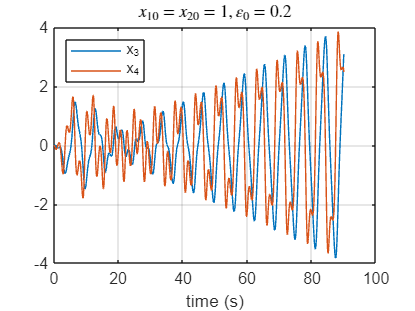

clear; close all;

x10 = 1;
x20 = 1;
[t,y] = ode45(@f, [0 90], [x10;x20;0;0]);

figure
plot(t,y(:,3:4))
legend('x_3','x_4','Location','northwest')
grid on
xlabel('time (s)')
title('$x_{10}=x_{20}=1, \varepsilon_0=0.2$','Interpreter','latex')

function [dydt] = f(~,y)
e = 0.2; % epsilon
dydt = zeros(4,1);
x1 = y(1);
x2 = y(2);
x3 = y(3);
x4 = y(4);
dydt(1) = x2;
dydt(2) = -x1 + e*(1-x1^2)*x2;
dydt(3) = x4;
dydt(4) = x3*(-1-2*e*x1*x2) + x4*e*(1-x1^2) + x2*(1-x1^2);
end